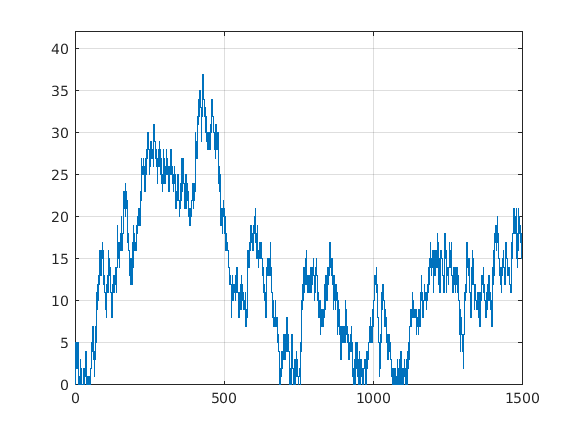

clc;
clear all;
close all;
% SIMMG1 simulate a M/G/1 queueing system. Poisson arrivals 
% of intensity lambda, uniform service times.
% 
% [jumptimes, systsize, systtime] = simmd1(tmax, lambda)
%
% Inputs: tmax - simulation interval
%         lambda - arrival intensity 
%
% Outputs: jumptimes - time points of arrivals or departures
%          systsize - system size in M/G/1 queue
%	       systtime - system times

  tmax=1500;                  % simulation interval 
  lambda=0.99;                 % arrival intensity 

arrtime=-log(rand)/lambda;  % Poisson arrivals
i=1;                  
  while (min(arrtime(i,:))<=tmax)
    arrtime = [arrtime; arrtime(i, :)-log(rand)/lambda];  
    i=i+1;
  end
n=length(arrtime);           % arrival times t_1,...,t_n         

servtime=2.*rand(1,n);          % service times s_1,...,s_k
cumservtime=cumsum(servtime);

arrsubtr=arrtime-[0 cumservtime(:,1:n-1)]';           % t_k-(k-1)
arrmatrix=arrsubtr*ones(1,n);        
deptime=cumservtime+max(triu(arrmatrix));  % departure times 
                                        % u_k=k+max(t_1,..,t_k-k+1)   

% Output is system size process N and system waiting 
% times W.
B=[ones(n,1) arrtime ; -ones(n,1) deptime']; 
Bsort=sortrows(B,2);                 % sort jumps in order
jumps=Bsort(:,1);
jumptimes=[0;Bsort(:,2)];
systsize=[0;cumsum(jumps)];          % size of M/G/1 queue
systtime=deptime-arrtime';            % system times 

figure(1)
stairs(jumptimes,systsize);
xmax=max(systsize)+5;
axis([0 tmax 0 xmax]);
grid

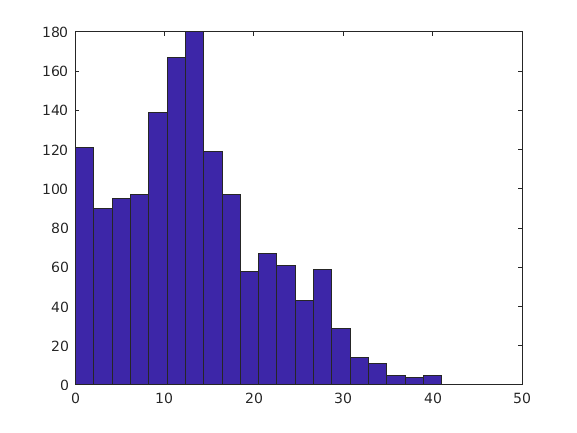


figure(2)
hist(systtime,20);

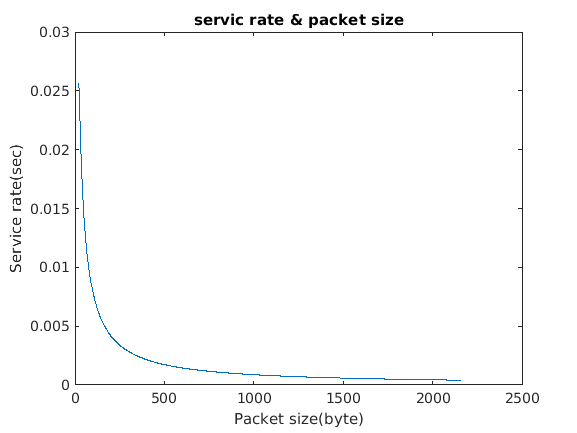


payload=1:1500; % payload size
for i = 1:length(payload)

  PL=payload;

end

%  SF=linspace(7,12,i);
SF=7;
%lamda=0.5;
                      
BW=125; %bandwidth 125khz
cr=1; %Lora code rate
h=0; %for lora header 
L_prem=8;                %formula
                         %L_payload = 8 +[(8PL-4SF+28+16-20H)/(4SF)]*(CR + 4)
T_symbol=(2^SF)/BW;
T_preamble=(L_prem+4.25).*T_symbol;
L_payload=8+(((8.*PL+4*SF+28+16-20*h)/(4*SF))*(cr+4));%message length


Packet_size=round(T_symbol.*L_payload);

ToA=T_preamble+Packet_size; % Time of Aire

%Dutcy=linspace(0.01, 0.001, i);
Dutcy=0.099.*ToA;
mu = Dutcy +ToA;

Service_time=1./mu;%service rate
Ro=lambda.*Service_time;  %Utilization factor

Delay=Packet_size.*Service_time;





figure(3)
plot(L_payload,Service_time);
title('servic rate & packet size');
 ylabel('Service rate(sec)');
 xlabel('Packet size(byte)');

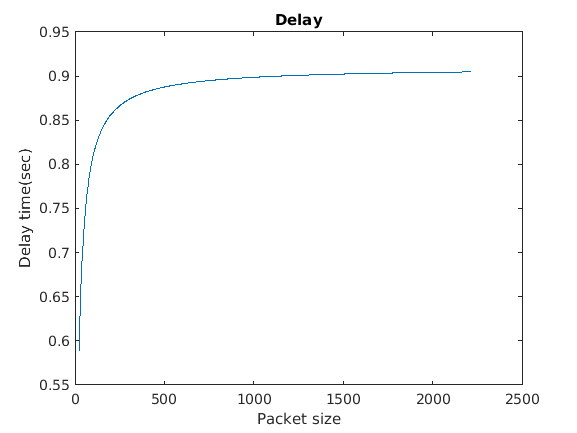


 
 
 
 figure(4)
 plot(Packet_size,Delay)
 title('Delay');
 ylabel('Delay time(sec)');
 xlabel('Packet size')